# Linear System Identification Example

`This script was put together for the YouTube video, "Linear System Identification | System Identification, Part 2". `

`Brian Douglas 2021`

## Create "real" system dynamics

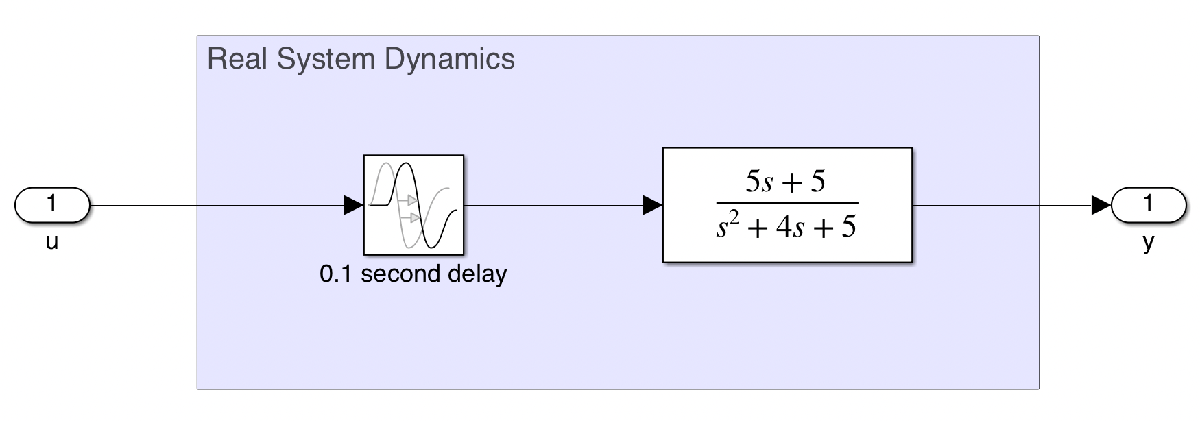

s = tf('s');
Greal = 5*(s + 1)/(s^2 + 4*s + 5) * exp(-0.1*s)

Greal =
 
                   5 s + 5
  exp(-0.1*s) * -------------
                s^2 + 4 s + 5
 
Continuous-time transfer function.



## Collect data

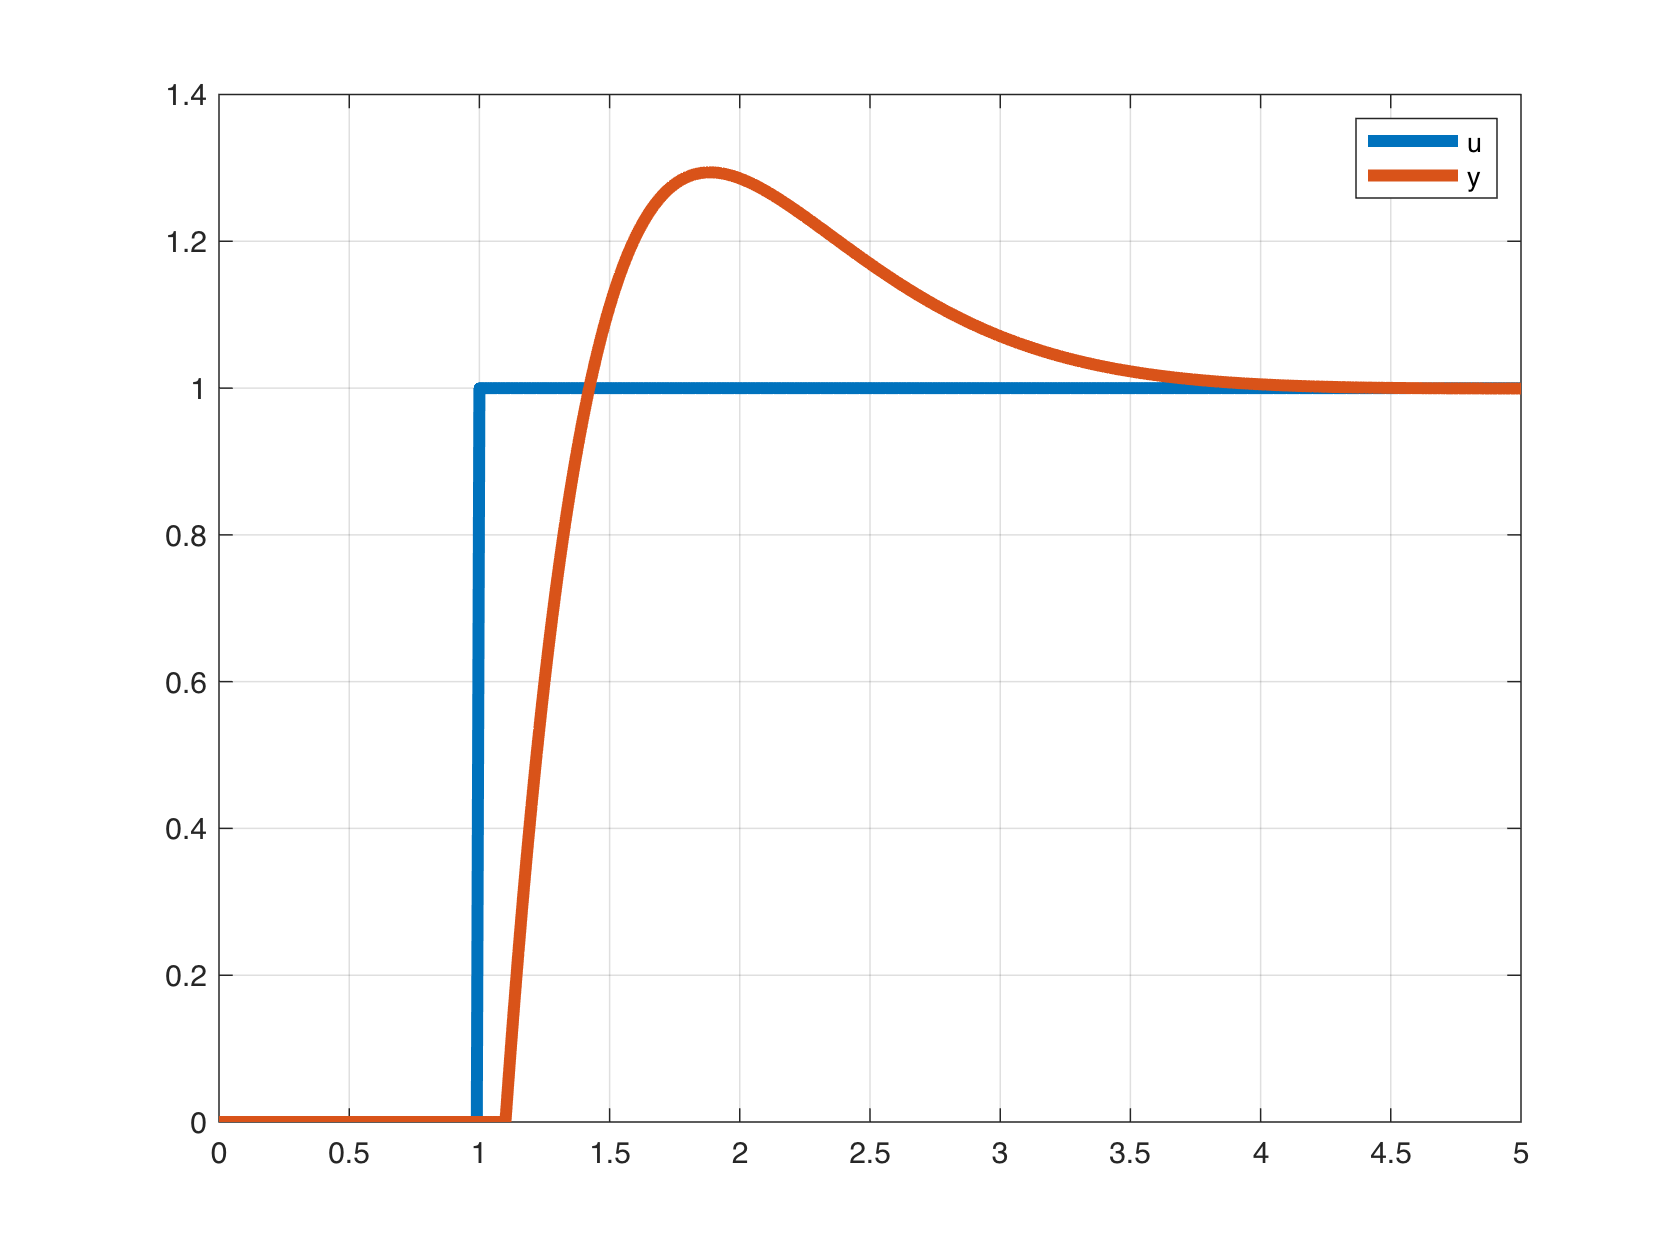

dt = 0.01;
t = 0:dt:5;

% Build the step input
u = ones(length(t), 1);
u(1:1/dt) = 0;

% Simulate a step response
yreal = lsim(Greal, u, t);

plot(t, [u, yreal], 'LineWidth', 4)
axis([0 5 0 1.4]);
grid on
legend(['u'; 'y']);

## Choose model structure

% At least 2nd order
% Transport delay

## Identify model by fitting it to the data

% Fit data to a transfer function with unknown delay term
data = iddata(yreal, u, dt);
Gest = tfest(data, 2, 0, NaN)

Gest =
 
  From input "u1" to output "y1":
                        85.45
  exp(-0.1*s) * ---------------------
                s^2 + 12.02 s + 78.38
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 81.32%                   
FPE: 0.007755, MSE: 0.007602                     


## Validate the model

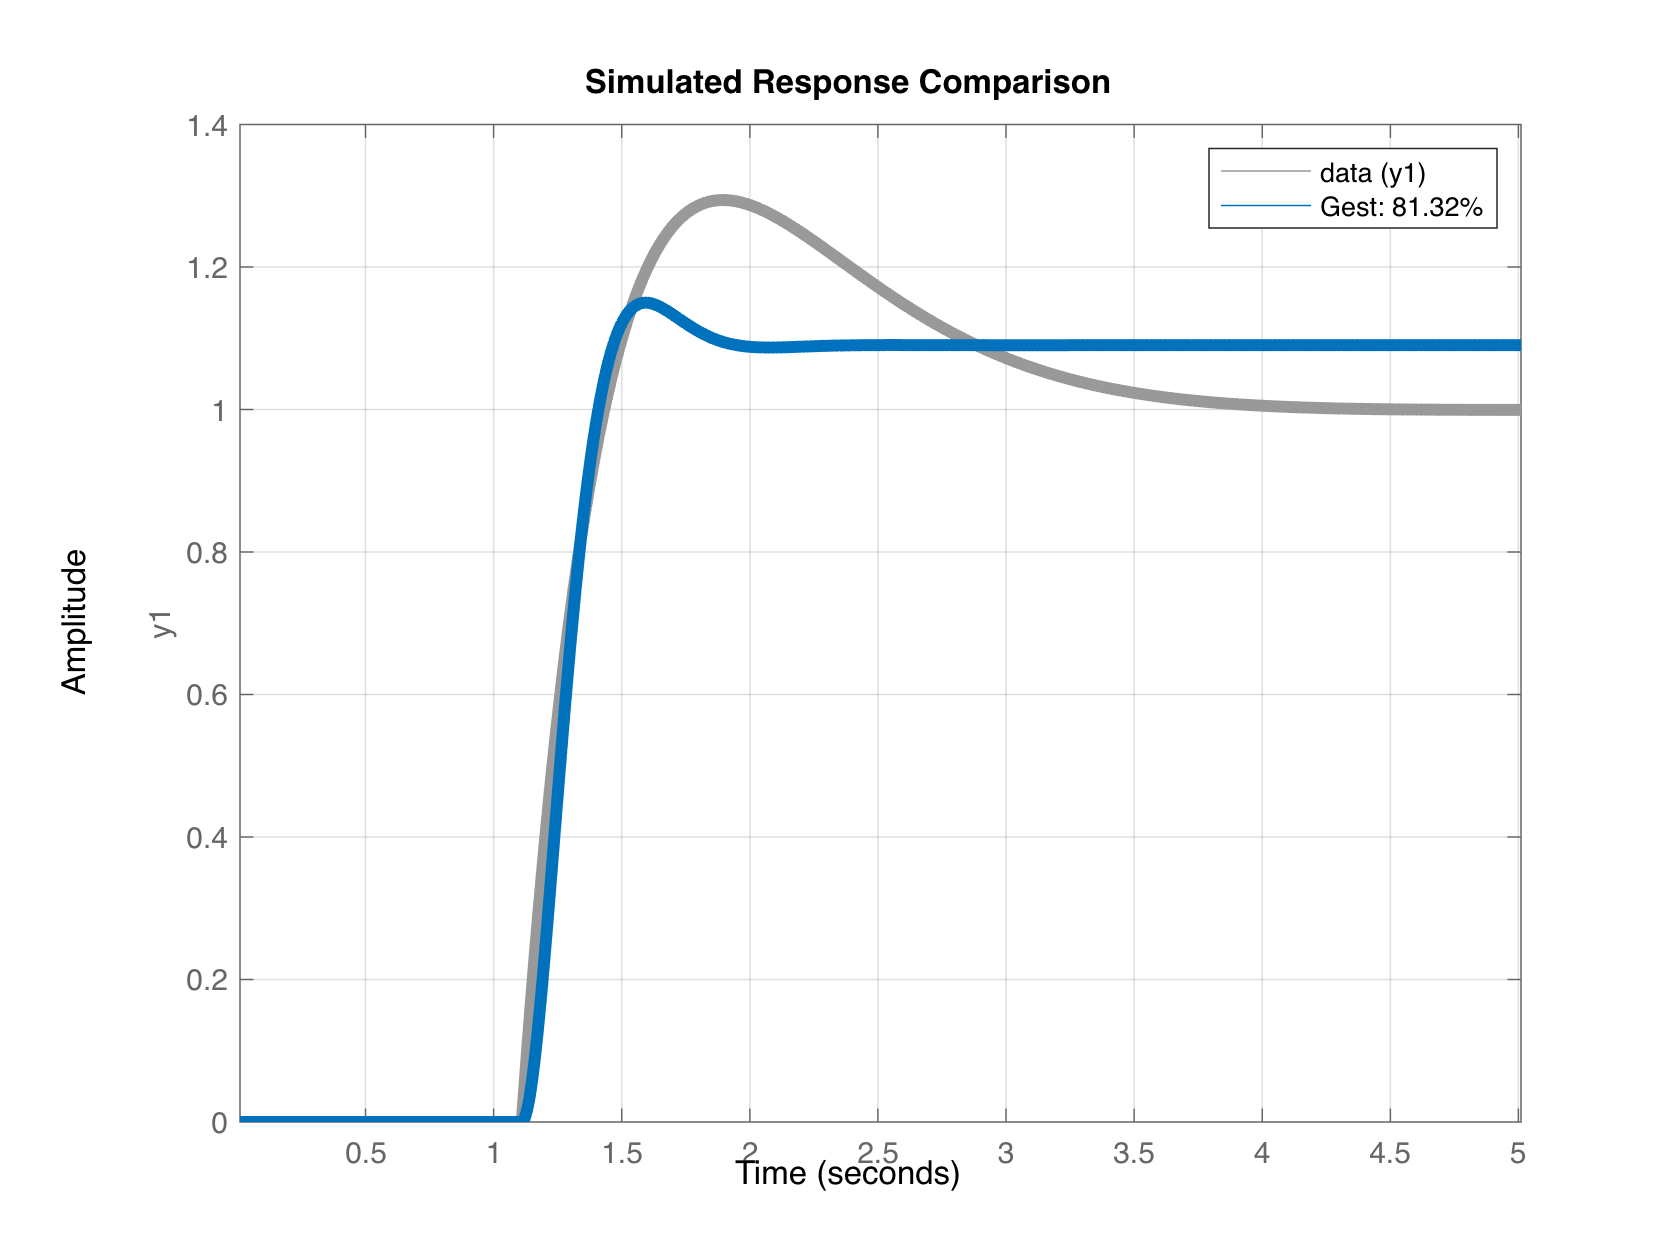

opt = compareOptions;
opt.InitialCondition = 'z';
compare(data, Gest, opt);
set(findall(gca, 'Type', 'Line'),'LineWidth',4);
grid on

## Identify a state space model

% Estimate the delay term
delay_samples = delayest(data);

% Remove delay from output
yreal_no_delay = yreal(delay_samples+1:end); 

% Repackage offset data
data_offset = iddata(yreal_no_delay, u(1:end-delay_samples), dt);

% Fit data to a state space model of unknown order
Gss = ssest(data_offset, 1:10)

Gss =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
            x1       x2
   x1   -2.876    4.268
   x2  -0.4143   -1.124
 
  B = 
           u1
   x1   -1.41
   x2  0.1438
 
  C = 
           x1      x2
   y1  -3.338   1.766
 
  D = 
       u1
   y1   0
 
  K = 
          y1
   x1  -31.7
   x2  -3.92
 
Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: estimate
   Number of free coefficients: 10
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using SSEST on time domain data "data_offset".
Fit to estimation data: 99.51% (prediction focus)       
FPE: 5.074e-06, MSE: 4.951e-06                          


% Convert to tf and add in the delay term
Gest = tf(Gss) * exp(-delay_samples * dt * s)

Gest =
 
  From input to output "y1":
                  4.96 s + 5
  exp(-0.11*s) * -------------
                 s^2 + 4 s + 5
 
Continuous-time transfer function.



## Validate the model

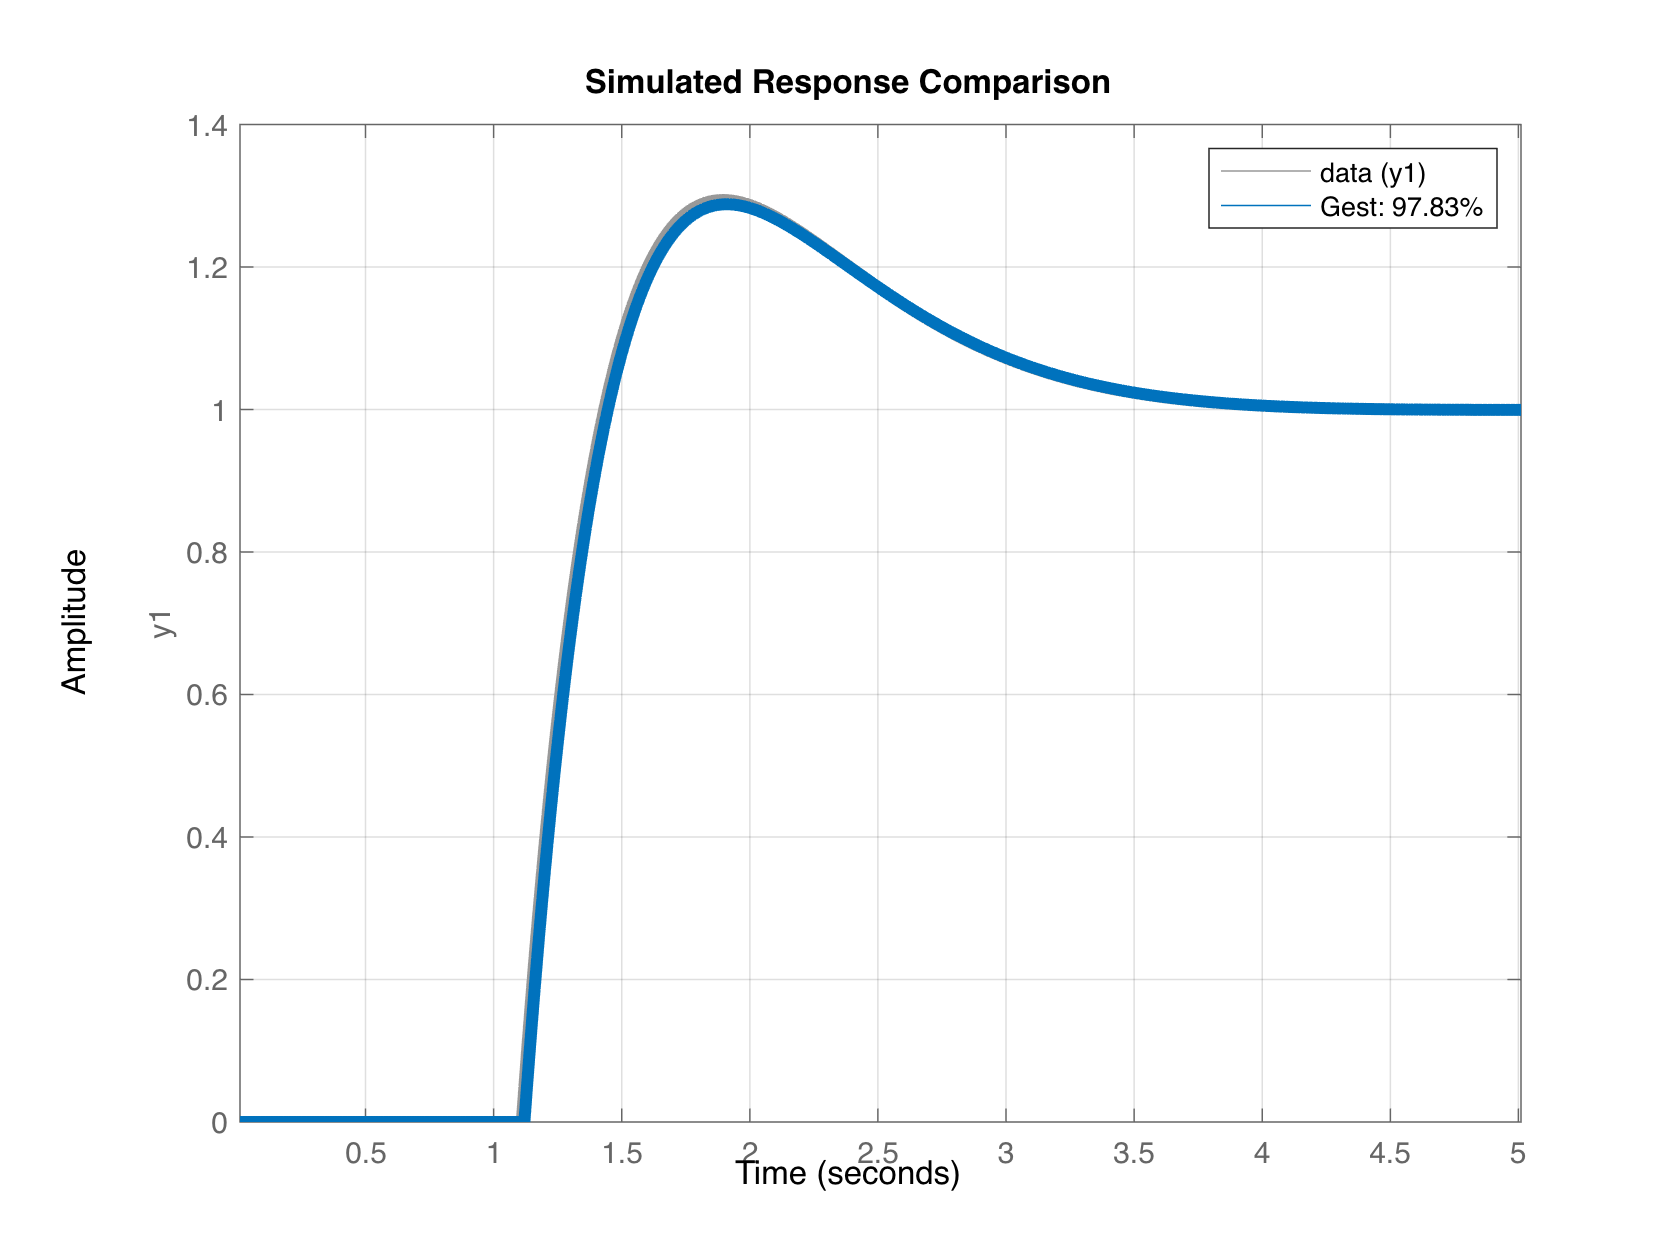

opt = compareOptions;
opt.InitialCondition = 'z';
compare(data,Gest,opt);
set(findall(gca, 'Type', 'Line'),'LineWidth',4);
grid on